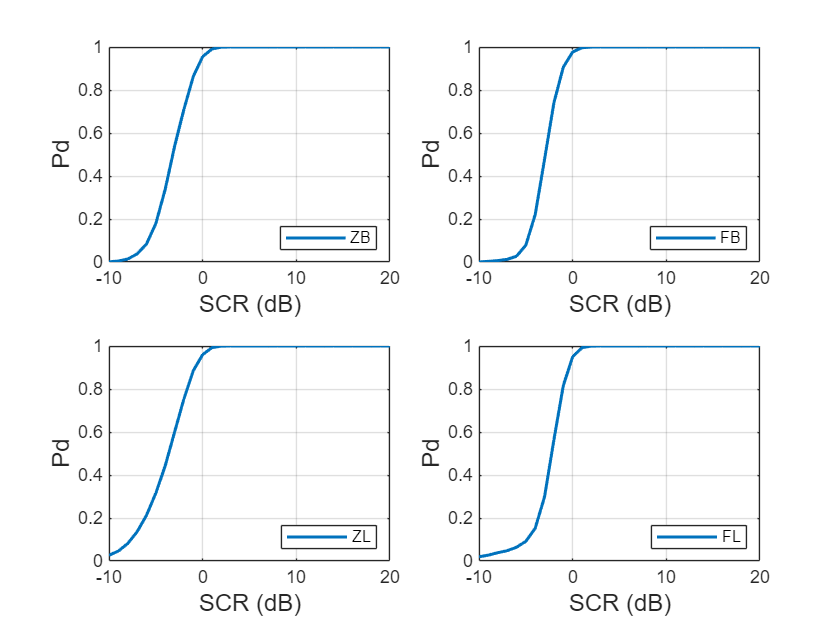

% GLRT-DT
DT_ZB=load('GLRTDT_ZB.mat').GLRTDT_result;
DT_ZL=load('GLRTDT_ZL.mat').GLRTDT_result;
DT_FB=load('GLRTDT_FB.mat').GLRTDT_result;
DT_FL=load('GLRTDT_FL.mat').GLRTDT_result;
figure;
SCR_list = -10:1:20;  % 保证这个是你用来生成数据的实际 SCR 列表
xlim([-10 20]);            % 设置横坐标范围
ylim([0 1]);               % 设置纵坐标范围（检测概率范围是0~1）
subplot(2,2,1);
plot(SCR_list, mean(DT_ZB,2)', 'LineWidth', 1.5);  % 横坐标用 SCR_list
xlabel('SCR (dB)', 'FontSize', 12);
ylabel('Pd', 'FontSize', 12);
legend('ZB', 'Location','southeast');grid on;
subplot(2,2,3);
plot(SCR_list, mean(DT_ZL,2)', 'LineWidth', 1.5);  % 横坐标用 SCR_list
xlabel('SCR (dB)', 'FontSize', 12);
ylabel('Pd', 'FontSize', 12);
legend('ZL', 'Location','southeast');grid on;
subplot(2,2,2);
plot(SCR_list, mean(DT_FB,2)', 'LineWidth', 1.5);  % 横坐标用 SCR_list
xlabel('SCR (dB)', 'FontSize', 12);
ylabel('Pd', 'FontSize', 12);
legend('FB', 'Location','southeast');grid on;
subplot(2,2,4);
plot(SCR_list, mean(DT_FL,2)', 'LineWidth', 1.5);  % 横坐标用 SCR_list
xlabel('SCR (dB)', 'FontSize', 12);
ylabel('Pd', 'FontSize', 12);
legend('FL', 'Location','southeast');grid on;

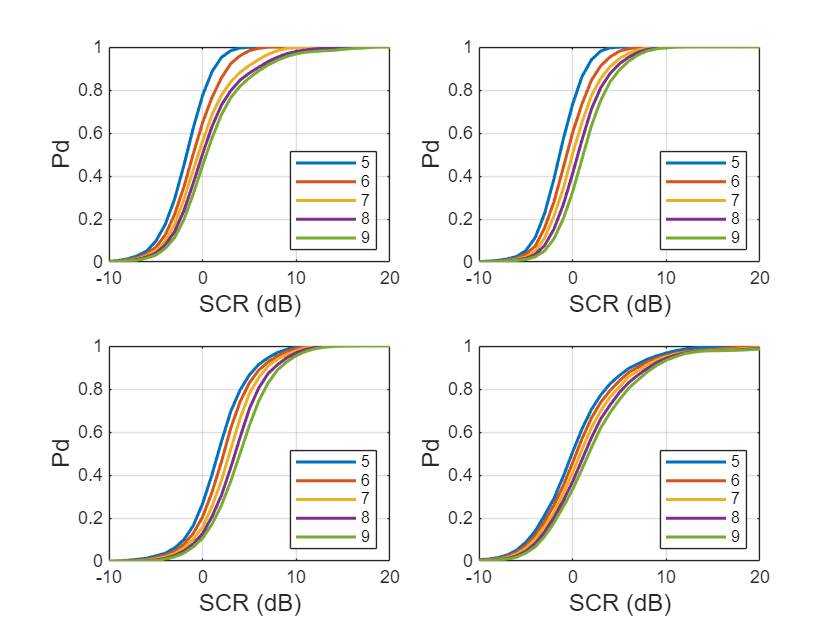

% MN
MN_ZB=load('MN_result_ZB.mat').MNdetector_result;
MN_ZL=load('MN_result_ZL.mat').MNdetector_result;
MN_FL=load('MN_result_FL.mat').MNdetector_result;
MN_FB=load('MN_result_FB.mat').MNdetector_result;
MN_ZB_ALL=load('MN_result_ZB_allcl.mat').MNdetector_result;
MN_ZL_ALL=load('MN_result_ZL_allcl.mat').MNdetector_result;
MN_FL_ALL=load('MN_result_FL_allcl.mat').MNdetector_result;
MN_FB_ALL=load('MN_result_FB_allcl.mat').MNdetector_result;
%%
% 单个训练一类杂波 
figure;
MNdetector_Th2_list=5:9;
SCR_list = -10:1:20;  % 保证这个是你用来生成数据的实际 SCR 列表
xlim([-10 20]);            % 设置横坐标范围
ylim([0 1]);               % 设置纵坐标范围（检测概率范围是0~1）
subplot(2,2,1);
plot(SCR_list,mean(MN_ZB,3),'LineWidth',1.5);
xlabel('SCR (dB)', 'FontSize', 12);
ylabel('Pd', 'FontSize', 12);
legend(num2str(MNdetector_Th2_list'), 'Location','southeast');grid on;
subplot(2,2,2);
plot(SCR_list,mean(MN_FB,3),'LineWidth',1.5);
xlabel('SCR (dB)', 'FontSize', 12);
ylabel('Pd', 'FontSize', 12);
legend(num2str(MNdetector_Th2_list'), 'Location','southeast');grid on;
subplot(2,2,3);
plot(SCR_list,mean(MN_FL,3),'LineWidth',1.5);
xlabel('SCR (dB)', 'FontSize', 12);
ylabel('Pd', 'FontSize', 12);
legend(num2str(MNdetector_Th2_list'), 'Location','southeast');grid on;
subplot(2,2,4);
plot(SCR_list,mean(MN_ZL,3),'LineWidth',1.5);
xlabel('SCR (dB)', 'FontSize', 12);
ylabel('Pd', 'FontSize', 12);
legend(num2str(MNdetector_Th2_list'), 'Location','southeast');grid on;

% 两类杂波一起训练
figure;
MNdetector_Th2_list_ALL=8:12

MNdetector_Th2_list_ALL =      8     9    10    11    12


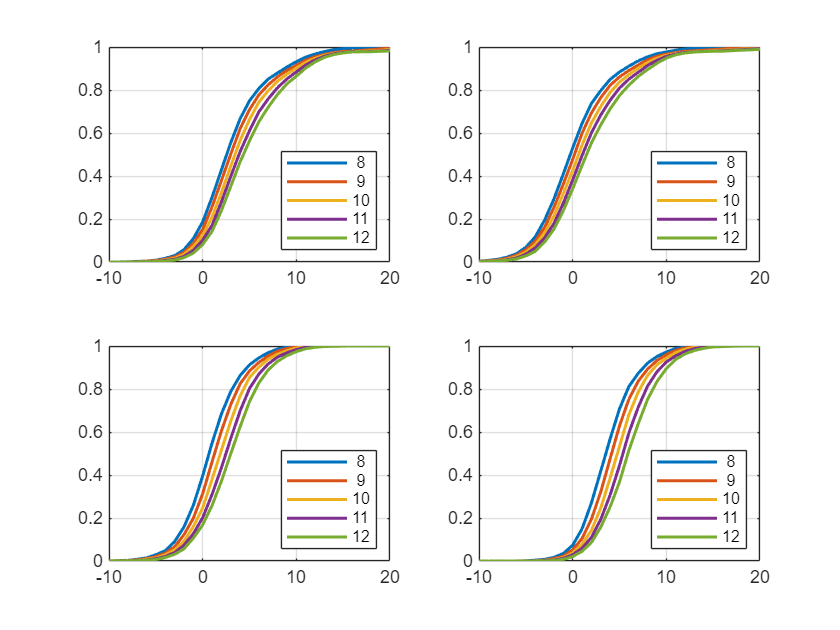

SCR_list = -10:1:20;  % 保证这个是你用来生成数据的实际 SCR 列表
xlim([-10 20]);            % 设置横坐标范围
ylim([0 1]);               % 设置纵坐标范围（检测概率范围是0~1）
xlabel('SCR (dB)', 'FontSize', 12);
ylabel('Detection Probability Pd', 'FontSize', 12);
subplot(2,2,1);
plot(SCR_list,mean(MN_ZB_ALL,3),'LineWidth',1.5);
legend(num2str(MNdetector_Th2_list_ALL'), 'Location','southeast');grid on;
subplot(2,2,2);
plot(SCR_list,mean(MN_ZL_ALL,3),'LineWidth',1.5);
legend(num2str(MNdetector_Th2_list_ALL'), 'Location','southeast');grid on;
subplot(2,2,3);
plot(SCR_list,mean(MN_FL_ALL,3),'LineWidth',1.5);
legend(num2str(MNdetector_Th2_list_ALL'), 'Location','southeast');grid on;
subplot(2,2,4);
plot(SCR_list,mean(MN_FB_ALL,3),'LineWidth',1.5);
legend(num2str(MNdetector_Th2_list_ALL'), 'Location','southeast');grid on;